# Working with Audio

## การอ่านไฟล์เสียง

audioFile1 = "Examples/Example1.wav";
audioFile2 = "Examples/Example2.wav";
audioFile3 = "Examples/Cycle1.wav";
audioFile4 = "Examples/Cycle2.wav";

[samples, Fs] = audioread(audioFile4);

- `x` คือ sample ของเสียงที่โหลดเข้ามา มีช่วงของค่าระหว่าง [-1.0, 1.0]

- `Fs` คือ sampling rate ในที่นี้คือ 48 kHz

fprintf("Sampling rate = %d Hz\n", Fs);

Sampling rate = 48000 Hz


fprintf("Audio length = %d samples (%.2f seconds)\n", length(samples), length(samples) / Fs);

Audio length = 242161 samples (5.05 seconds)



fprintf("The first few samples:\n");

The first few samples:


disp(samples(1:100));

    0.1333
    0.2117
    0.1287
    0.0829
    0.2359
    0.1237
   -0.1887
   -0.2267
   -0.3942
   -0.1801
   -0.1460
   -0.0660
    0.0773
    0.0923
    0.1819
    0.0413
    0.0418
   -0.0463
   -0.0416
    0.0522
    0.0726
   -0.0101
   -0.0716
    0.0294
    0.0583
    0.0626
   -0.0759
    0.1239
    0.2791
    0.0941
    0.0376
   -0.0712
    0.1393
    0.0945
    0.0597
    0.0862
    0.0055
    0.0520
    0.0804
    0.2218
    0.1459
    0.1736
    0.1080
    0.0324
    0.2692
    0.0562
   -0.0829
    0.1089
    0.2911
    0.3064
    0.3357
    0.2534
    0.0847
   -0.1642
   -0.1609
   -0.3246
   -0.3698
   -0.0672
    0.2944
    0.3601
    0.1476
    0.1936
    0.2117
    0.1387
    0.0514
   -0.2023
   -0.3916
   -0.3444
   -0.3224
   -0.1624
    0.0666
    0.0820
    0.0236
    0.1447
    0.1288
    0.0489
   -0.1566
   -0.0738
    0.0175
   -0.0680
   -0.1757
   -0.2935
   -0.2714
   -0.2582
   -0.2317
   -0.1858
    0.0144
   -0.0130
    0.0308
    0.0609
    0.1165

## การแสดงและเล่นไฟล์เสียง

    plot(x, y)

    array index start at 1

    time = samples / Fs

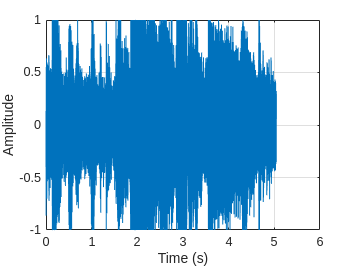

% chunk = samples(1:4800);
chunk = samples(1:end);

% Display the waveform
plot((1:length(chunk))/Fs, chunk);
xlabel("Time (s)");
ylabel("Amplitude");
grid("on");

audioplayer used for play sound

% Playback the samples
player = audioplayer(samples, Fs); % must specify correct sampling rate
play(player);

stop(player); % use when wanting to stop long audio playback

ans = -3.3031e-04

## สัญญาณทดสอบ

linspace(init, end, number of array)

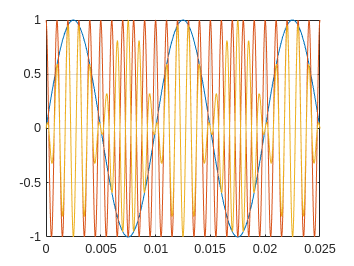

signalTime = 0.025; % total time in seconds
t = linspace(0, signalTime, round(signalTime * Fs));

testSignal1 = sin(2 * pi * 100 * t);
testSignal2 = cos(2 * pi * 1000 * t);
testSignal3 = testSignal1 .* testSignal2;

plot(t, testSignal1);
hold on;
plot(t, testSignal2);
plot(t, testSignal3);
hold off;
grid("on");

player = audioplayer(testSignal3, Fs); % must specify correct sampling rate
play(player);

## การบันทึกไฟล์เสียง

audiowrite("Examples/TestSignal.wav", testSignal3, Fs);